close all;
xdata1=[0:0.01:0.2].*180*100;
figure;
plot(xdata1,ydata1,'.','markersize',30,'Color',[239 111 108]./255);

函数或变量 'ydata1' 无法识别。

xlabel('556 Frequency Modulation (kHz)');
ylabel('Sum of OD');
title('556 Spectrum');
set(gca,'fontsize',28);
grid on;
hold on;
fitxdata1=[0:0.001:0.2].*180*100;
a1=137.5;
gamma1=6.762;
x01=11.02;
fitydata1=a1*gamma1/2./((fitxdata1./100-x01).^2+gamma1^2/4);
plot(fitxdata1,fitydata1,'LineWidth',2,'LineStyle',"--",'Color',[239 111 108]./255);


xdata2=[0:0.01:0.2].*180*100;

plot(xdata2,ydata2,'.','markersize',30,"Color",[92 158 173]./255);
xlabel('556 Frequency Modulation (kHz)');
ylabel('Sum of OD');
title('556 Spectrum');
set(gca,'fontsize',30);
grid on;
hold on;
fitxdata2=[0:0.001:0.2].*180*100;
a2=139;
gamma2=8.954;
x02=12.39;
fitydata2=a2*gamma2/2./((fitxdata2./100-x02).^2+gamma2^2/4);
plot(fitxdata2,fitydata2,'LineWidth',2,'Color',[92 158 173]./255);
legend('Trap off','','Trap on','','fontsize',40)
set(gca,'fontname','times new roman')


close all;
figure;
subplot(3,1,1);
plot(time,position,'LineWidth',0.5);
title('Position (mm)');
grid on;
set(gca,'fontsize',20,'fontname','times new roman')

subplot(3,1,2);
plot(time,velocity,'LineWidth',0.5);
title('Velocity (mm/s)')
grid on;
set(gca,'fontsize',20,'fontname','times new roman')

subplot(3,1,3);
plot(time,acceleration,'LineWidth',0.5);
title('Acceleration (mm/s^2)');
xlabel('Time (s)');
grid on;
set(gca,'fontsize',20,'fontname','times new roman')

close all;
figure;
time=[20:-0.5:0.5];
fittime=[0.01:0.01:20];
fity=180*exp(-fittime./31.52);
plot(fittime,fity,'linewidth',2);
hold on;
plot(time,ODsum1,'.','markersize',15);
ylabel('Sum of OD');
xlabel('Time (s)');
set(gca,'fontsize',20,'fontname','times new roman')



close all;
figure;
time=[11:1:40];
plot(time,relativeOD,'.',"MarkerSize",35);
hold on;
fplot(@(x) 0.4553*sin(2*pi/12.41*x-4.61)+0.05508,[10 40],'linewidth',4);
ylim([-1 1]);
xlabel('Precession time (ms)');
ylabel('S_z');
set(gca,'fontname','times new roman','fontsize',30)

close all;
figure1=figure;
importfile('C:\Users\14684\Desktop\Thesis\thesis data\data_averaged\171rabi.mat');
time=[5:5:100 505:5:600 1005:5:1100 1505:5:1600 2005:5:2100];
rabiweight=1./rabierror.^2
errorbar(time,rabiphase,rabierror,'.','capsize',1,'MarkerSize',25,'LineWidth',1);
xlim([0 2100]);
set(gca,'fontname','times new roman','fontsize',30);
xlabel('Rabi Oscillation Time (\mus)','interpreter','tex')
ylabel('S_z');
hold on;
fitx=[0:0.1:2100];
       a =  -0.8871 ;
       b =  -1.619 ;
       c =    -0.00123  ;
       t =   54.63  ;
       tau =    1273 ;
 fity=a*sin(2*pi/t.*fitx+b).*exp(-fitx/tau)+c;
 plot(fitx,fity,'linewidth',2);
 axes2 = axes('Parent',figure1,...
    'Position',[0.484895833333333 0.726787620064034 0.400572916666635 0.180362860192114]);
hold(axes2,'on');
errorbar(time,rabiphase,rabierror,'.','capsize',1,'MarkerSize',25,'LineWidth',1);
plot(fitx,fity,'linewidth',2);
set(axes2,'FontName','times new roman','FontSize',20,'Box','on');
grid on;
xlim(axes2,[0 100]);

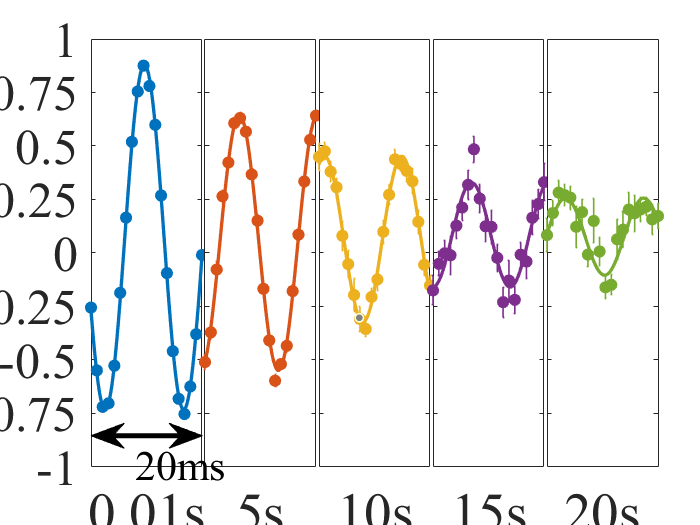

close all;
figure1=figure;
importfile('C:\Users\14684\Desktop\Thesis\thesis data\data_averaged\171ramsey.mat');
time=[[0.001:0.001:0.02]+0.01 [0.001:0.001:0.02]+5 [0.001:0.001:0.02]+10 [0.001:0.001:0.02]+15 [0.001:0.001:0.02]+20];
ramseyweight=1./ramseyerror.^2;
% errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1);
% xlim([0 21]);
axes('Parent',figure1,'Position',[0.13 0.11 0.1590625 0.815]);
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color','#0072BD');
xlim([0.001 0.02]+0.01);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'0.01s');
ylabel('S_z');
yticks([-1:0.25:1]);
fitx=[0.001:0.0001:0.02]+0.01;
a =       0.805  ;
       b =       4.726 ;
       c =     0.07342  ;
       t =     0.01345 ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx,fity,'linewidth',2,'color','#0072BD');
hold off;


axes2 = axes('Parent',figure1,...
    'Position',[0.29281512605042 0.11 0.1590625 0.815]);
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color','#D95319');
xlim([0.001 0.02]+5);
ylim([-1,1]);
set(gca,'yTickLabel',[],'fontname','times new roman','fontsize',30);
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'5s');
yticks([-1:0.25:1]);
fitx=[0.001:0.0001:0.02];
       a =      0.5962  ;
       b =       4.618  ;
       c =     0.04762  ;
       t =     0.01336  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+5,fity,'linewidth',2,'color','#D95319');
hold off;



axes3 = axes('Parent',figure1,...
    'Position',[0.45563025210084 0.11 0.1590625 0.815]);
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color','#EDB120');
xlim([0.001 0.02]+10);
ylim([-1,1]);
set(gca,'yTickLabel',[],'fontname','times new roman','fontsize',30);
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'10s');
yticks([-1:0.25:1]);
fitx=[0.001:0.0001:0.02];
       a =      0.3863  ;
       b =      0.6524  ;
       c =     0.06537  ;
       t =     0.01323  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+10,fity,'linewidth',2,'color','#EDB120');
hold off;


axes4 = axes('Parent',figure1,...
    'Position',[0.618445378151261 0.11 0.1590625 0.815]);
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color','#7E2F8E');
xlim([0.001 0.02]+15);
ylim([-1,1]);
set(gca,'yTickLabel',[],'fontname','times new roman','fontsize',30);
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'15s');
yticks([-1:0.25:1]);
fitx=[0.001:0.0001:0.02];
       a =      -0.244  ;
       b =        1.11  ;
       c =     0.08499  ;
       t =     0.01323  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+15,fity,'linewidth',2,'color','#7E2F8E');
hold off;


axes5 = axes('Parent',figure1,...
    'Position',[0.781260504201681 0.11 0.1590625 0.815]);
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color','#77AC30');
xlim([0.001 0.02]+20);
set(gca,'xtick',0,'XTickLabel','0')
ylim([-1,1]);
set(gca,'yTickLabel',[],'fontname','times new roman','fontsize',30);
xlabel(gca,'20s');
yticks([-1:0.25:1]);
fitx=[0.001:0.0001:0.02];
       a =        0.18  ;
       b =     -0.3952  ;
       c =     0.07648  ;
       t =     0.01337  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+20,fity,'linewidth',2,'color','#77AC30');
hold off;


annotation(figure1,'textbox',...
    [0.1806875 0.149413020277481 0.0516041666666667 0.0202774813233725],...
    'String','20ms',...
    'FontSize',25,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(figure1,'doublearrow',[0.13 0.13+0.1590625],...
    [0.17 0.17],'LineWidth',3,'Head2Width',20,'Head2Length',20,'Head1Width',20,...
    'Head1Length',20);

    close all;
figure1=figure;
       tcenter=[0.01345 0.01336 0.01323 0.01323 0.01337];
       sigmat=[0.000035 0.00008 0.000175 0.000535 0.000695];
       sigmaf=sigmat./tcenter.^2./0.7499;
       weight=1./sigmaf.^2;
       fcenter=1./tcenter./0.7499;
       timelist=[0.01 5 10 15 20];
       errorbar(timelist,fcenter,sigmaf,'.k','capsize',1,'MarkerSize',25,'LineWidth',1,'color','#0072BD');
       ylabel('B (mGauss)');
       xlabel('Time (s)');
       sum(fcenter.*weight)/(sum(weight))

ans = 99.3037

       sum(sigmaf.*weight)/sum(weight)

ans = 0.3645

      sum(fcenter.*weight)/(sum(weight))*0.7499

ans = 74.4679

      sum(sigmaf.*weight)/sum(weight)*0.7499

ans = 0.2734

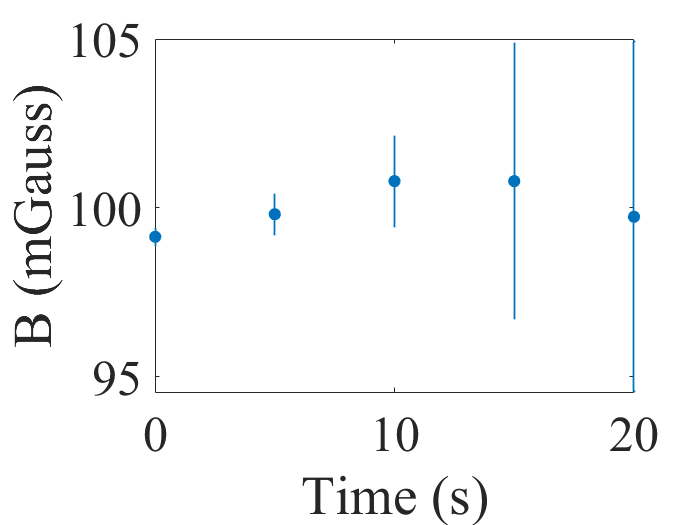

       set(gca,'fontname','times new roman','fontsize',30);

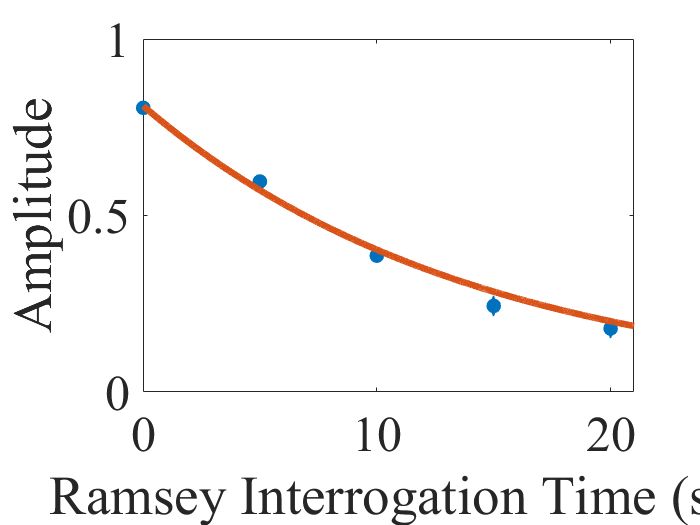

close all;
figure1=figure;
  ampcenter=[0.805 0.5962 0.3863 0.244 0.18];
  amperror=[0.0061 0.00855 0.012 0.025 0.0229];
  timelist=[0.01 5 10 15 20];
  weight=1./amperror.^2;
  errorbar(timelist,ampcenter,amperror,'.k','capsize',1,'MarkerSize',30,'LineWidth',2,'color','#0072BD');
  xlim([0 21]);
  ylim([0 1]);
  set(gca,'fontname','times new roman','fontsize',30);
  fitx=[0.01:0.01:21];
  fity=0.8108*exp(-fitx./14.31);
  hold on;
  plot(fitx,fity,'linewidth',4);
  xlabel('Ramsey Interrogation Time (s)');
  ylabel('Amplitude');

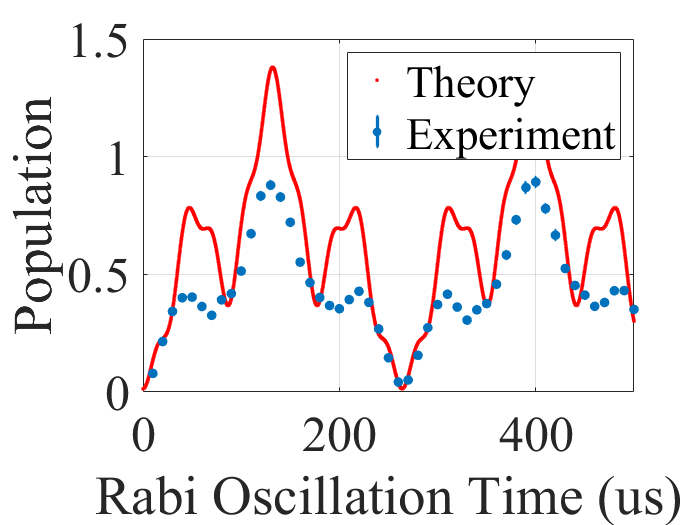

close all;
importfile('C:\Users\14684\Desktop\Thesis\thesis data\data_averaged\173rabi.mat');
sigma_x=spinOp(5/2,'x');
sigma_y=spinOp(5/2,'y');
sigma_z=spinOp(5/2,'z');
adjust=0.0238;
ham=adjust*(sigma_x+sigma_x^2);
initial=[1 0 0 0 0 0];
time=[0:0.1:500];
state=solve_ham(ham,initial,time);

plot(time,2.3*(0.6*abs(state(6,:)).^2+0.0093*abs(state(5,:)).^2+0.00595*abs(state(4,:)).^2+0.3557*abs(state(3,:)).^2+0.3179*abs(state(2,:)).^2+0.006*abs(state(1,:)).^2),'.','Color','r');
hold on;
realtime=[10:10:500];
errorbar(realtime,phaseaverage,phaseerr,'.k','capsize',1,'MarkerSize',20,'LineWidth',2,'color','#0072BD');
xlim([0 500]);
set(gca,'box','on','FontName','times new roman','fontsize',30);
grid on;
xlabel('Rabi Oscillation Time (us)');
ylabel('Population');
legend('Theory','Experiment');

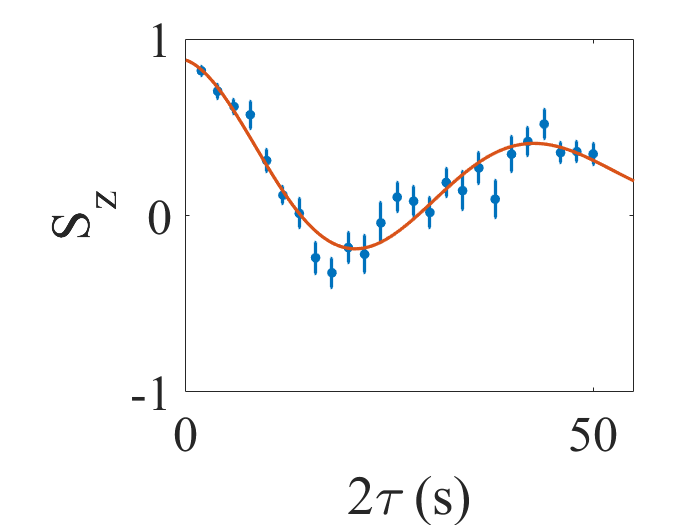

close all;
importfile('C:\Users\14684\Desktop\Thesis\thesis data\data_averaged\171spinecho.mat');
realtime=[2:2:50];
weight=1./phaseerr.^2;
errorbar(realtime,phaseaverage,phaseerr,'.k','capsize',1,'MarkerSize',20,'LineWidth',2,'color','#0072BD');
ylim([-1 1]);
xlim([0 55])
set(gca,'box','on','FontName','times new roman','fontsize',30);
xlabel('2\tau (s)');
ylabel('S_z');
hold on;
fitx=[0.1:0.1:55];
       a =       0.687  ;
       b =      -11.03  ;
       c =      0.1958  ;
       f =     0.02283  ;
       tau =       37.02  ;
fity=a*exp(-fitx./tau).*sin(2*pi*f.*fitx+b)+c;
plot(fitx,fity,'linewidth',2);

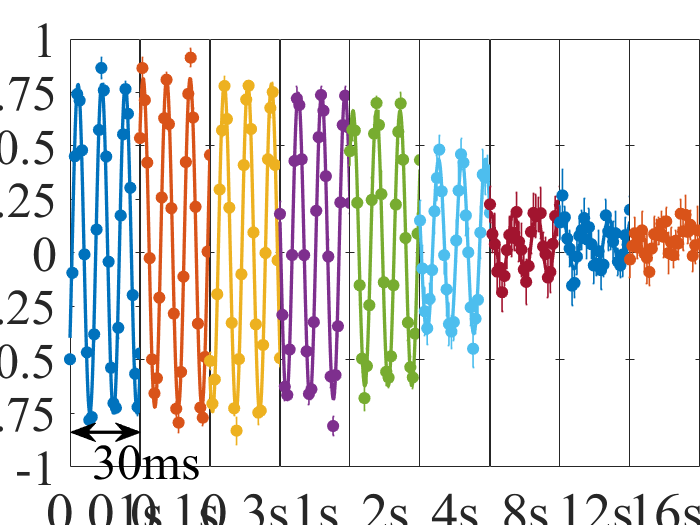

close all;
figure1=figure;
color1='#0072BD';color2='#D95319';color3='#EDB120';color4=	'#7E2F8E';color5='#77AC30';
color6='#4DBEEE';color7=	'#A2142F';color8='#0072BD';color9='#D95319';
importfile('C:\Users\14684\Desktop\Thesis\thesis data\data_averaged\173ramsey.mat');
ramseyphase=phaseaverage;
ramseyerror=phaseerr;

time=[[0.001:0.001:0.03]+0.01 [0.001:0.001:0.03]+0.1 [0.001:0.001:0.03]+0.3 [0.001:0.001:0.03]+1 [0.001:0.001:0.03]+2 [0.001:0.001:0.03]+4 [0.001:0.001:0.03]+8 [0.001:0.001:0.03]+12 [0.001:0.001:0.03]+16];
ramseyweight=1./ramseyerror.^2;
% errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1);
% xlim([0 21]);

axes1 = axes('Parent',figure1,...
    'Position',[0.10 0.11 0.1 0.815]);
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color','#0072BD');
xlim([0.001 0.03]+0.01);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'0.01s');
ylabel('S_z');
yticks([-1:0.25:1]);
fitx=[0.001:0.0001:0.03]+0.01;
       a =      0.7693  ;
       b =      -1.343  ;
       c =     0.01935  ;
       t =    0.009796  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx,fity,'linewidth',2,'color','#0072BD');
hold off;

axes2 = axes('Parent',figure1,...
    'Position',[0.20 0.11 0.1 0.815]);
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color2);
xlim([0.001 0.03]+0.1);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'box','on');
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'0.1s');
ylabel([]);
yticklabels([]);
fitx=[0.001:0.0001:0.03];
       a =      0.7693  ;
       b =     0.09385  ;
       c =     0.04754  ;
       t =    0.009742  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+0.1,fity,'linewidth',2,'color',color2);
hold off;

axes3 = axes('Parent',figure1,...
    'Position',[0.3 0.11 0.1 0.815]);
hold(axes3,'on');
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color3);
xlim([0.001 0.03]+0.3);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'box','on');
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'0.3s');
ylabel([]);
yticklabels([]);
fitx=[0.001:0.0001:0.03];
       a =      -0.767  ;
       b =      0.2612  ;
       c =     0.02388  ;
       t =    0.009771  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+0.3,fity,'linewidth',2,'color',color3);
hold off;

axes4 = axes('Parent',figure1,...
    'Position',[0.4 0.11 0.1 0.815]);
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color4);
xlim([0.001 0.03]+1);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'box','on');
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'1s');
ylabel([]);
yticklabels([]);
fitx=[0.001:0.0001:0.03];
       a =      0.7154  ;
       b =       2.335  ;
       c =     0.03168  ;
       t =    0.009719  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+1,fity,'linewidth',2,'color',color4);
hold off;

axes5 = axes('Parent',figure1,...
    'Position',[0.5 0.11 0.1 0.815]);
hold(axes5,'on');
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color5);
xlim([0.001 0.03]+2);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'box','on');
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'2s');
ylabel([]);
yticklabels([]);
fitx=[0.001:0.0001:0.03];
       a =      0.6439  ;
       b =      0.1217  ;
       c =      0.0222  ;
       t =    0.009748  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+2,fity,'linewidth',2,'color',color5);
hold off;

axes6 = axes('Parent',figure1,...
    'Position',[0.6 0.11 0.1 0.815]);
hold(axes6,'on');
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color6);
xlim([0.001 0.03]+4);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'box','on');
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'4s');
ylabel([]);
yticklabels([]);
fitx=[0.001:0.0001:0.03];
       a =      0.4086  ;
       b =       2.206 ;
       c =     0.03037  ;
       t =    0.009704  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+4,fity,'linewidth',2,'color',color6);
hold off;

axes7 = axes('Parent',figure1,...
    'Position',[0.7 0.11 0.1 0.815]);
hold(axes7,'on');
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color7);
xlim([0.001 0.03]+8);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'box','on');
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'8s');
ylabel([]);
yticklabels([]);
fitx=[0.001:0.0001:0.03];
       a =      0.1512  ;
       b =      0.7898  ;
       c =     0.03924  ;
       t =    0.009594  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+8,fity,'linewidth',2,'color',color7);
hold off;

axes8 = axes('Parent',figure1,...
    'Position',[0.8 0.11 0.1 0.815]);
hold(axes8,'on');
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color8);
xlim([0.001 0.03]+12);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'box','on');
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'12s');
ylabel([]);
yticklabels([]);
fitx=[0.001:0.0001:0.03];
       a =      0.1179  ;
       b =       0.248  ;
       c =     0.04415  ;
       t =     0.00959  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+12,fity,'linewidth',2,'color',color8);
hold off;

axes9 = axes('Parent',figure1,...
    'Position',[0.9 0.11 0.1 0.815]);
hold(axes9,'on');
errorbar(time,ramseyphase,ramseyerror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color9);
xlim([0.001 0.03]+16);
ylim([-1,1]);
set(gca,'fontname','times new roman','fontsize',30)
set(gca,'box','on');
set(gca,'xtick',0,'XTickLabel','0')
xlabel(gca,'16s');
ylabel([]);
yticklabels([]);
fitx=[0.001:0.0001:0.02];
       a =     0.05343  ;
       b =      -1.595  ;
       c =     0.06134  ;
       t =    0.009339  ;
fity=a*sin(2*pi/t.*fitx+b)+c;
hold on;
plot(fitx+16,fity,'linewidth',2,'color',color9);
hold off;

annotation(figure1,'doublearrow',[0.101041666666667 0.200520833333333],...
    [0.176680896478122 0.176680896478122],'LineWidth',2,'Head2Width',15,...
    'Head2Length',15,...
    'Head1Width',15,...
    'Head1Length',15);

% 创建 textbox
annotation(figure1,'textbox',...
    [0.119229166666667 0.156883671291355 0.0463958333333333 0.0288153681963715],...
    'String',{'30ms'},...
    'FontSize',30,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

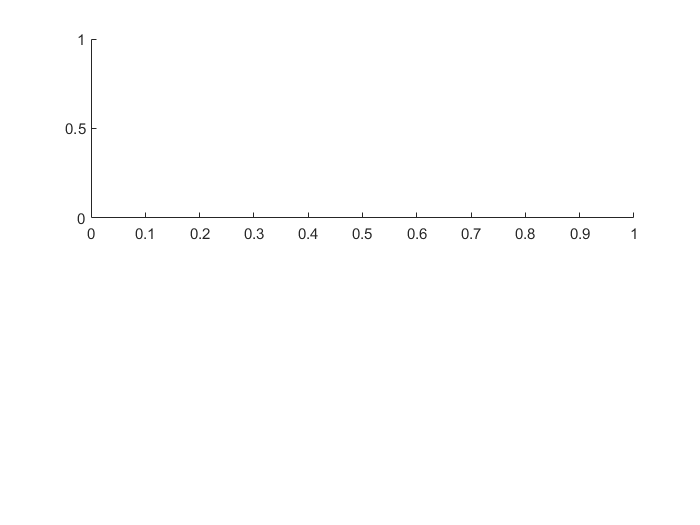

close all;
figure1=figure;
subplot(2,1,1);

plot(detune,vector,'.','markersize',15,"Color",color1);

函数或变量 'vector' 无法识别。

ylim([-10000000 10000000]);
title('Polarizability');
ylabel('Vector \alpha_{nJF}^v (a.u.)')
set(gca,'fontname','times new roman','fontsize',30)

subplot(2,1,2);
plot(detune,tensor,'.','markersize',15,"Color",color2);
ylim([-10000000 10000000]);
ylabel(['Tensor \alpha_{nJF}^T (a.u.)'])
xlabel('Detuning (MHz)')
set(gca,'fontname','times new roman','fontsize',30)

close all;
figure1=figure;
color1='#0072BD';color2='#D95319';color3='#EDB120';color4=	'#7E2F8E';color5='#77AC30';
color6='#4DBEEE';color7=	'#A2142F';color8='#0072BD';color9='#D95319';
plot(detune,ratio,'.','markersize',15,'color',color1);
ylim([-3 3]);
hold on;
fplot(@(x) 1,[-1000 7000],'linestyle',"--",'linewidth',2,'color',color4);

fplot(@(x) -1,[-1000 7000],'linestyle',"--",'linewidth',2,'color',color5);

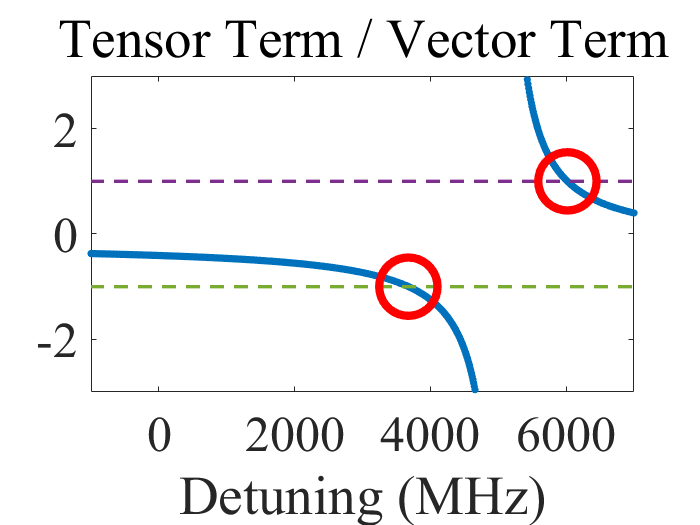

set(gca,'fontname','times new roman','fontsize',30)
xlabel('Detuning (MHz)');
title('Tensor Term / Vector Term')
plot(3675.84,-1,'o','markersize',35,'color','r','linewidth',5);
plot(6019.06,+1,'o','markersize',35,'color','r','linewidth',5);

close all;
timelist=[0.01 0.1 0.3 1 2 4 8 12 16];
ampcenter=[0.7693 0.7696 0.767 0.7154 0.6439 0.4086 0.1512 0.1179 0.05343];
amperror=[0.0127 0.015 0.01225 0.00765 0.01185 0.0131 0.01435 0.01513 0.013595];
ampweight=1./amperror.^2;

periodcenter=[0.009796 0.009742 0.009771 0.009719 0.009748 0.009704 0.009594 0.009590 0.009339];
perioderror=[25 28.5 29 21 43 63 189.5 237.5 403].*0.000001;
periodweight=1./perioderror.^2;
fcenter=1./periodcenter;
ferror=perioderror./(periodcenter.^2);
fweight=1./ferror.^2;
bcenter=sum(fweight.*fcenter)/sum(fweight)

bcenter = 102.5659

berror=sum(fweight.*ferror)/sum(fweight)

berror = 0.3065

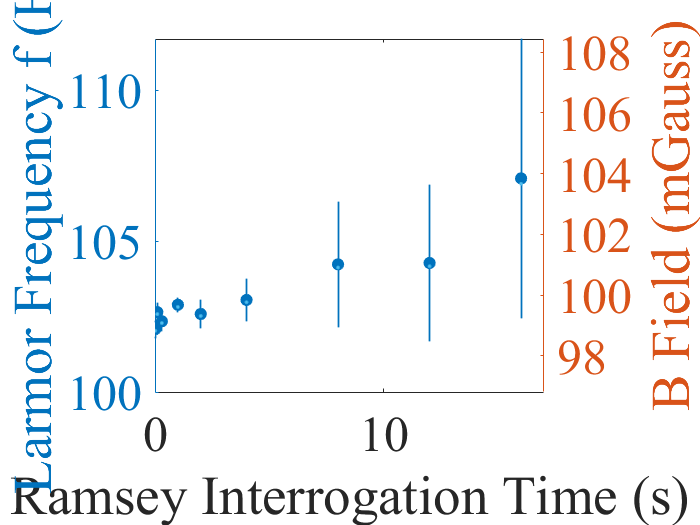

bplotcenter=fcenter./103.29.*100;

figure;
yyaxis left;

errorbar(timelist,fcenter,ferror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color1);
ylabel('Larmor Frequency f (Hz)');
hold on;
yyaxis right;
plot(timelist, bplotcenter,'.','color',color6);
ylabel('B Field (mGauss)');
ylim([100 112]./1.0329);

set(gca,'fontname','times new roman','fontsize',30)
xlabel('Ramsey Interrogation Time (s)');
xlim([0 17]);

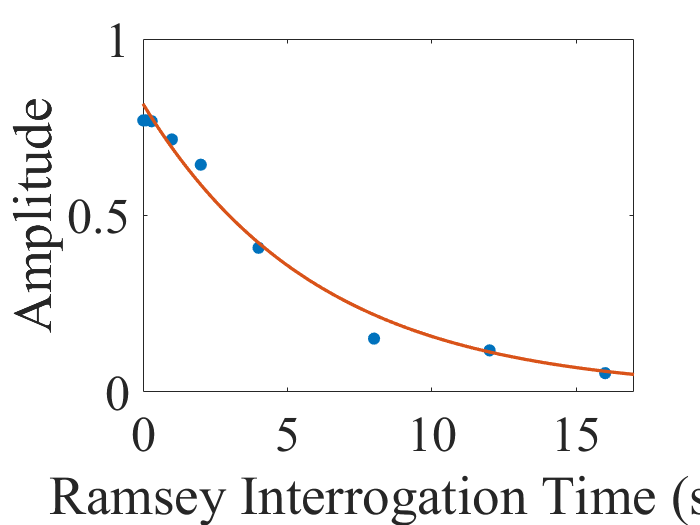


figure;
errorbar(timelist,ampcenter,amperror,'.','capsize',1,'MarkerSize',25,'LineWidth',1,'color',color1);

set(gca,'fontname','times new roman','fontsize',30)
ylabel('Amplitude');
xlabel('Ramsey Interrogation Time (s)');
xlim([0 17]);
hold on;
fitx=[0:0.1:17];
fity=0.8163*exp(-fitx./6.078);
plot(fitx,fity,'LineWidth',2)